# **Exploratory Simulations**

In this live script, we simulate jump-changes in a scalar random field and explore the detection of these changes using the residuals from a Karhunen-Loeve expansion.

Some questions of note:

- How tight is the Chebychev bound on the residual under the null hypothesis?

- How sensitive is the detection to changes in the mean function?

- How sensitive is the detection to changes in the covariance function? 

- How well can we estimate the eigenvalues and eigenfunctions?

**Setup:**

Consider the domain $U = [0,1]$. Let $v(x,\omega)$ be a Gaussian process on $U$ with mean 0 and covariance $Cov(v(x,\omega),v(y,\omega)) = \exp(-(x-y)^2/L)$. Define $w(x,\omega) = \mu_A$.  

*Random Field Parameters:*

mu_A = 3;
L    = 0.1;

After training on realizations of $\nu(x,\omega)$, we seek to detect the change $w(x,\omega)$ when observing a new realization of the form $u(x,\omega) = v(x,\omega)+w(x,\omega)$.

*Number of measurements (grid size to evaluate functional observations)*

n_measurements = 100;

*Number of functional observations to "train" and "test":*

n_realizations_train = 100000; 
n_realizations_test = 1000;

*Number of eigenvalues to take:*

m = 3;

*Alpha level for hypothesis test:*

significance_level = 0.05;

**Properties of the residual distribution**

Under the null hypothesis (where the stochastic process is given by $v(x,\omega)$), we can obtain a bound on variance of the residuals $R = \int (\sum_{k=m+1}^{\infty}\rho_k \phi_k(x))^2 dx$  in the following way:

Since $\phi_k$ are uncorrelated and the summand is nonnegative,

$\mathbb{E}( \int \sum_{k=m+1}^{\infty}(\rho_k \phi_k(x))^2dx = \mathbb{E}(\sum_{k=1m+1}^{\infty}\int \rho_k^2 \phi^2_k(x)dx)$.

As the $\phi_k$ are orthonormal, this reduces to

$\sum_{k=m+1}^{\infty}\mathbb{E}(\rho_k^2) = \sum_{k=m+1}^{\infty}Var(\rho_k) = \sum_{k=m+1}^{\infty}\lambda_k$.

Therefore, Markov's inequality yields that for any $\alpha > 0$ we can write


$$\Pr \left(|R|\ge \frac{\sum_{k=m+1} {\lambda_k } \;}{\alpha \;}\right)\le \alpha \;\ldotp$$


**Simulation:**

Our realizations will be measured on a grid at $n$ equally spaced locations. We will train on the training observations to estimate the eigenfunctions and eigenvalues. Then, we will generate new observations and measure the size of the residuals. 

*How many realizations to plot:*

n_realizations_to_plot = 10

n_realizations_to_plot = 10

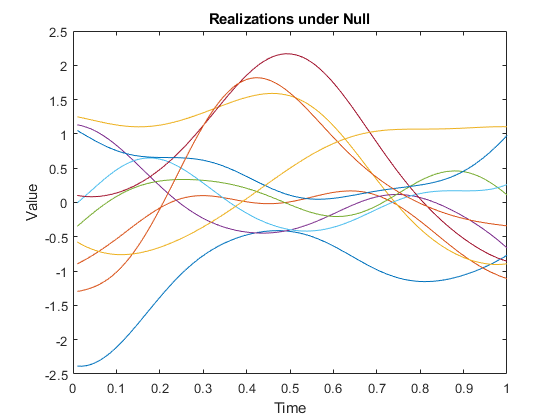

training_realizations = simulate_gaussian_process(n_measurements,n_realizations_train,0,L);
alternative_realizations = simulate_gaussian_process(n_measurements,n_realizations_train,mu_A,L);

time = (1/n_measurements):(1/n_measurements):1;

plot(time,training_realizations(1:n_realizations_to_plot,1:end)');
hold on;
title("Realizations under Null");
xlabel("Time");
ylabel("Value");
hold off;

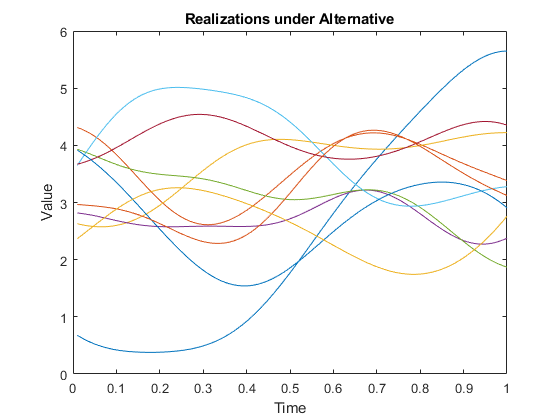

plot(time,alternative_realizations(1:n_realizations_to_plot,1:end)');
hold on;
title("Realizations under Alternative");
xlabel("Time");
ylabel("Value");
hold off;

*KL-Expansion:*

Here we compute the KL-expansion and plot the eigenvalues and eigenvectors:

sample_covariance = cov(training_realizations);

rootW = diag(ones(n_measurements,1)*1/sqrt(n_measurements));

[V,D] = eig(rootW*sample_covariance*rootW);
[eigenvalues,ind] = sort(diag(D),'descend');
V = V(:,ind)*sqrt(n_measurements)

V =     0.4980   -1.0065    1.4375    1.8424    2.1791    2.4328    2.6484    2.7664    2.8413    2.8505    2.8046    2.7326    2.6008    2.4432    2.2708    2.0823    1.8827    1.6766   -0.1907    0.0555    0.1345   -0.0699   -0.2182    0.0109   -0.5289   -0.0527   -0.0230    0.3204   -0.7825   -0.2733    0.8221    0.5405    0.8184   -0.6295   -0.4513    0.3512    0.6503   -0.4150    0.1547   -0.2348   -0.4622    0.7376    0.0763   -0.2850   -0.1636    0.2643    0.0007    0.4730   -0.0952    0.1926
    0.5187   -1.0351    1.4445    1.7848    2.0028    2.0778    2.0420    1.8539    1.5660    1.1767    0.7156    0.2142   -0.3089   -0.8165   -1.2932   -1.7160   -2.0705   -2.3380    0.0506    0.0588   -0.7855    0.4729    0.2746   -0.2358    1.4609    0.1325   -0.1445   -0.8819    1.4138    0.7391   -2.3090   -1.5806   -2.0028    1.8360    0.8964   -0.6234   -1.1682    1.0188   -1.0442    0.3525    1.6961   -1.5640    0.1538    0.8868    0.5843   -0.0850    0.0458   -0.9350   -0.0925   -1

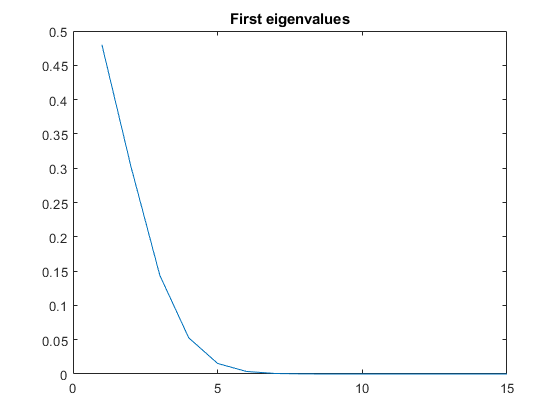


plot(eigenvalues(1:15));
title("First eigenvalues")

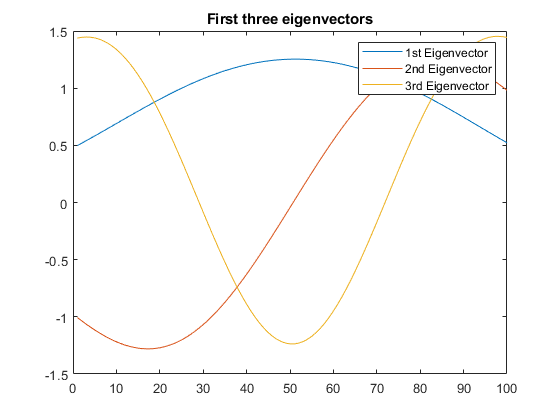


plot(V(1:end,1:3))
hold on
title("First three eigenvectors")
legend(["1st Eigenvector","2nd Eigenvector","3rd Eigenvector"])
hold off

*Residuals under null hypothesis:*


%A = ones(n_measurements,1)
%null_A = null(A')
%proj_V = null_A*null_A'*V
%V = orth(proj_V)

resid = (training_realizations)'-V(1:end,1:m)*V(1:end,1:m)'*(training_realizations)'/n_measurements;

sq_norm = vecnorm(resid).^2/n_measurements;

conservative_bound = sum(eigenvalues((m+1):end))/significance_level

conservative_bound = 1.4528

quantile_bound = quantile(sq_norm,1-significance_level)

quantile_bound = 0.2259

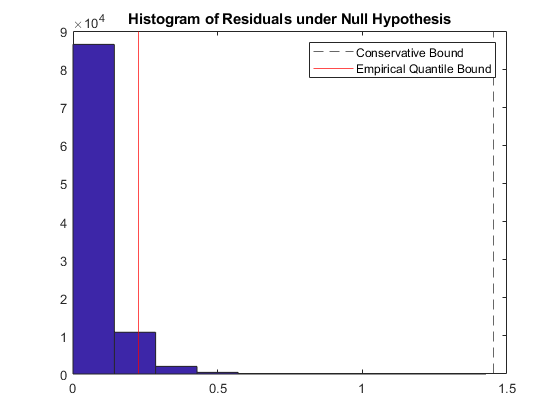


hist(sq_norm)
xline(conservative_bound,"--")
xline(quantile_bound,"red")
legend(["","Conservative Bound","Empirical Quantile Bound"])
title("Histogram of Residuals under Null Hypothesis")

%mu_A =V(1:end,m+1)%


*Residuals under alternative (jump change):*

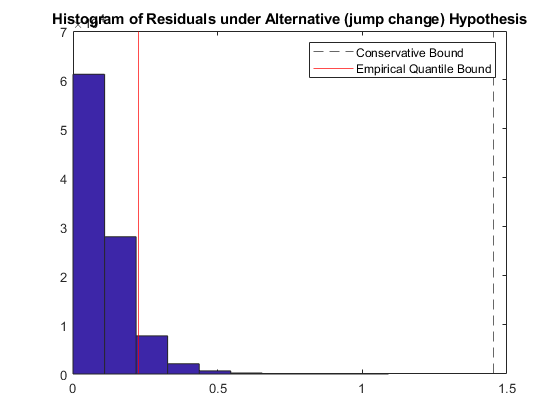




resid_alt = (alternative_realizations)'-V(1:end,1:m)*V(1:end,1:m)'*(alternative_realizations)'/n_measurements;


sq_norm_alt = vecnorm(resid_alt).^2/n_measurements;

hist(sq_norm_alt)
xline(conservative_bound,"--")
xline(quantile_bound,"red")
legend(["","Conservative Bound","Empirical Quantile Bound"])
title("Histogram of Residuals under Alternative (jump change) Hypothesis")

*Residuals under alternative (orthogonal change given by next eigenfunction):*

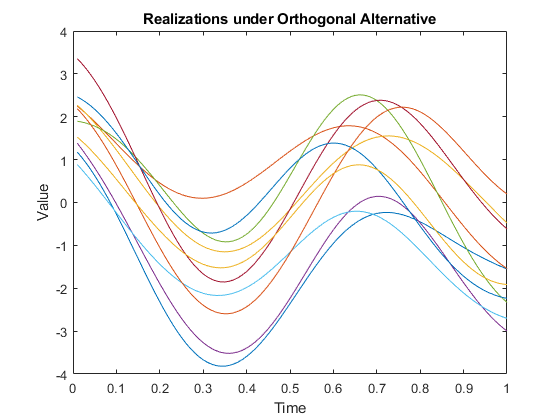

orthogonal_alternative_realizations = simulate_gaussian_process(n_measurements,n_realizations_train,V(1:end,m+1),L);

plot(time,orthogonal_alternative_realizations(1:n_realizations_to_plot,1:end)');
hold on;
title("Realizations under Orthogonal Alternative");
xlabel("Time");
ylabel("Value");
hold off;

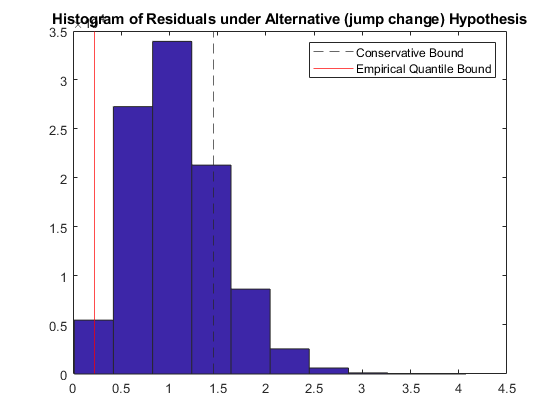


resid_orthogonal = (orthogonal_alternative_realizations)'-V(1:end,1:m)*V(1:end,1:m)'*(orthogonal_alternative_realizations)'/n_measurements;


sq_norm_orthogonal = vecnorm(resid_orthogonal).^2/n_measurements;

hist(sq_norm_orthogonal)
xline(conservative_bound,"--")
xline(quantile_bound,"red")
legend(["","Conservative Bound","Empirical Quantile Bound"])
title("Histogram of Residuals under Alternative (jump change) Hypothesis")

**Experimenting with the detection of jump changes**

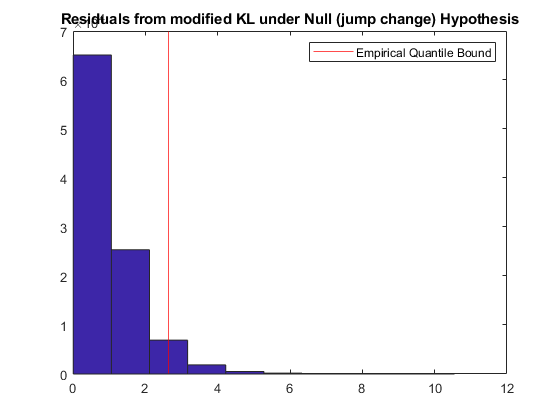

A = ones(n_measurements,1);
null_A = null(A');
proj_V = null_A*null_A'*V;
V2 = orth(proj_V);

resid2 = (training_realizations)'-V2(1:end,1:m)*V2(1:end,1:m)'*(training_realizations)'/n_measurements;
sq_norm2 = vecnorm(resid2).^2/n_measurements;

resid_alt2 = (alternative_realizations)'-V2(1:end,1:m)*V2(1:end,1:m)'*(alternative_realizations)'/n_measurements;
quantile_bound2 = quantile(sq_norm2,1-significance_level);

sq_norm_alt2 = vecnorm(resid_alt2).^2/n_measurements;

hist(sq_norm2)
xline(quantile_bound2,"red")
legend(["","Empirical Quantile Bound"])
title("Residuals from modified KL under Null (jump change) Hypothesis")

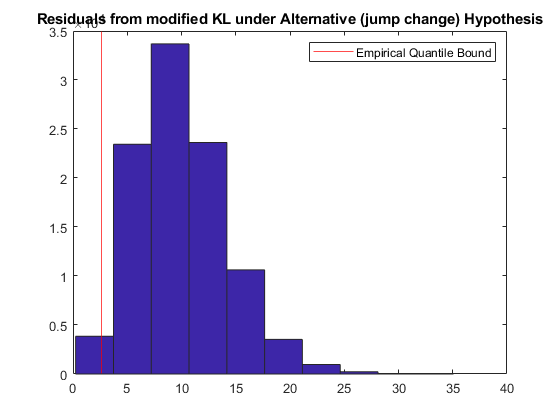


hist(sq_norm_alt2)
xline(quantile_bound2,"red")
legend(["","Empirical Quantile Bound"])
title("Residuals from modified KL under Alternative (jump change) Hypothesis")


mean(sq_norm_alt2 > quantile_bound2)

ans = 0.9884

function [realizations] = simulate_gaussian_process(n_measurements,n_observations,mu,L)
    % Produces a matrix whose rows are realizations from a gaussian
    % process and whose columns correspond to locations in a grid.
    % - n_measurements is the size of the grid on which each functional
    % observation is evaluated
    % - n_observations is the number of realizations to sample
    % - mu is the constant mean to sample from 
    % - L is the covariance parameter
    
    x = 0:(1/n_measurements):1;
    Sigma = zeros(n_measurements);
    mean_function = ones(n_measurements,1).*mu;
    
    for j = 1:n_measurements 
        for k = 1:n_measurements
            Sigma(j,k) = exp(-(x(j)-x(k))^2/L);
        end
    end
    
    realizations = mvnrnd(mean_function,Sigma,n_observations);
        
end
